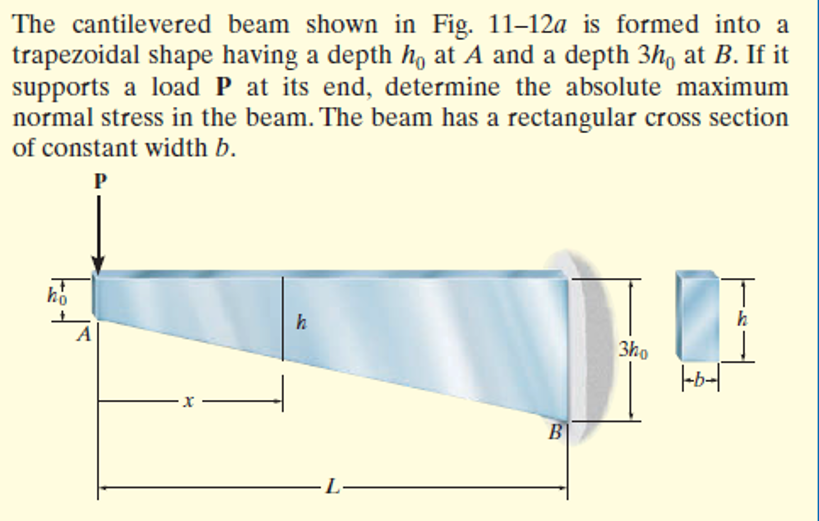

# assumptions

old_assum = assumptions;
clearassum;

# given

x = sym('x');
Ho = sym('Ho');
P = sym('P');
L = sym('L');

# beam

b = beam;
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('reaction', 'moment', 'Mb', L);
b = b.add('applied', 'force', -P, 0);

# section properties

B = sym('B');
H = findpoly(1, 'thru', [0 Ho], [L 3*Ho]);
b.I = B*H^3/12;

# elastic curve

[y dy m v w r] = b.elastic_curve([], 'factor'); %#ok
y = combine(y, 'log', 'IgnoreAnalyticConstraints', true)

$$y(x) = -\frac{L^{2}\,P\,\left(\log\left({\left(\frac{3\,L}{L+2\,x}\right)}^{9\,L^{2}+18\,x\,L}\right)-2\,L\,x-8\,L^{2}+10\,x^{2}\right)}{6\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,\left(L+2\,x\right)}$$

dy

$$dy(x) = \frac{2\,L^{2}\,P\,\left(L-x\right)\,\left(L+5\,x\right)}{3\,B\,\text{E}\,{\mathrm{Ho}}^{3}\,{\left(L+2\,x\right)}^{2}}$$

m

$$m(x) = -P\,x$$

v

$$v(x) = -P$$

w

$$w(x) = 0$$

addvar(y);

# shear and moment diagram

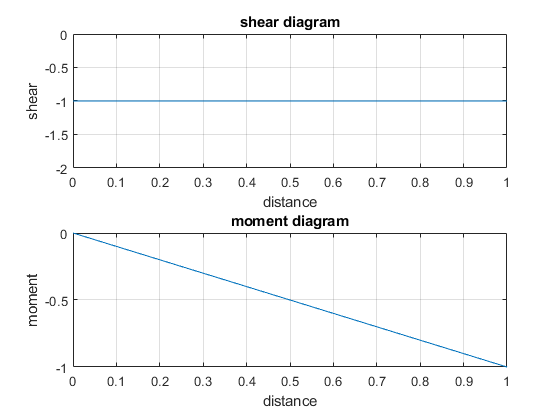

beam.shear_moment(m, v, [0 1], P, 1);

# maximum bending stress

C = H/2;
sigma(x) = -m*C/b.I;
x_max = solve(diff(sigma) == 0)

$$x\_max = \frac{L}{2}$$

sigma_max = sigma(x_max)

$$sigma\_max = \frac{3\,L\,P}{4\,B\,{\mathrm{Ho}}^{2}}$$